# Iris dataset

Clear workspace

clear all; clc; close all;

## Initialize variables

Load table

iris = readtable('Iris.csv')

iris = 150×6 table
    Id    SepalLengthCm    SepalWidthCm    PetalLengthCm    PetalWidthCm        Species    
    __    _____________    ____________    _____________    ____________    _______________

     1         5.1             3.5              1.4             0.2         {'Iris-setosa'}
     2         4.9               3              1.4             0.2         {'Iris-setosa'}
     3         4.7             3.2              1.3             0.2         {'Iris-setosa'}
     4         4.6             3.1              1.5             0.2         {'Iris-setosa'}
     5           5             3.6              1.4             0.2         {'Iris-setosa'}
     6         5.4             3.9              1.7             0.4         {'Iris-setosa'}
     7         4.6             3.4      

## Get a preview and some general stats

summary(iris)

Variables:

    Id: 150×1 double

        Values:

            Min            1  
            Median      75.5  
            Max          150  

    SepalLengthCm: 150×1 double

        Values:

            Min         4.3   
            Median      5.8   
            Max         7.9   

    SepalWidthCm: 150×1 double

        Values:

            Min           2   
            Median        3   
            Max         4.4   

    PetalLengthCm: 150×1 double

        Values:

            Min            1  
            Median      4.35  
            Max          6.9  

    PetalWidthCm: 150×1 double

        Values:

            Min         0.1   
            Median      1.3   
            Max         2.5   

    Species: 150×1 cell array of character vectors



Change Species column to categorical

iris.Species = categorical(iris.Species)

iris = 150×6 table
    Id    SepalLengthCm    SepalWidthCm    PetalLengthCm    PetalWidthCm      Species  
    __    _____________    ____________    _____________    ____________    ___________

     1         5.1             3.5              1.4             0.2         Iris-setosa
     2         4.9               3              1.4             0.2         Iris-setosa
     3         4.7             3.2              1.3             0.2         Iris-setosa
     4         4.6             3.1              1.5             0.2         Iris-setosa
     5           5             3.6              1.4             0.2         Iris-setosa
     6         5.4             3.9              1.7             0.4         Iris-setosa
     7         4.6             3.4              1.4             0.3     

All columns with explicative variables

X = iris(:,[2:end-1]);
xnames = X.Properties.VariableNames

xnames = 1×4 cell array
    {'SepalLengthCm'}    {'SepalWidthCm'}    {'PetalLengthCm'}    {'PetalWidthCm'}


Get categorical variable possible values

categories = unique(iris.Species)

categories = 3×1 categorical array
     Iris-setosa 
     Iris-versicolor 
     Iris-virginica 


color = lines(size(categories))

color =          0    0.4470    0.7410
    0.8500    0.3250    0.0980
    0.9290    0.6940    0.1250


GGplot to see each variable against another scatter plots

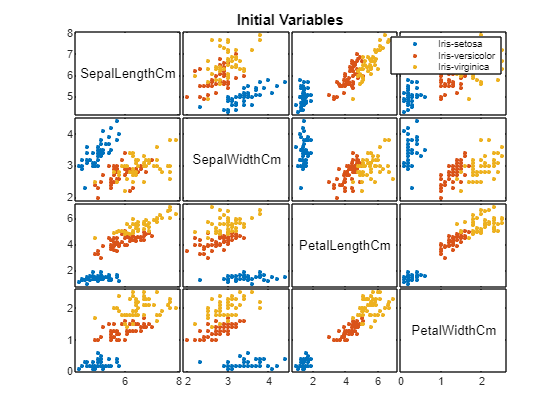

[h, ax] = gplotmatrix(table2array(X),[],iris.Species,color,[],[],[],'variable',xnames);
title('Initial Variables')

% saveas(gcf,'01_Iris/Initial_vars.png')

## Generate some derivated variables which may be useful

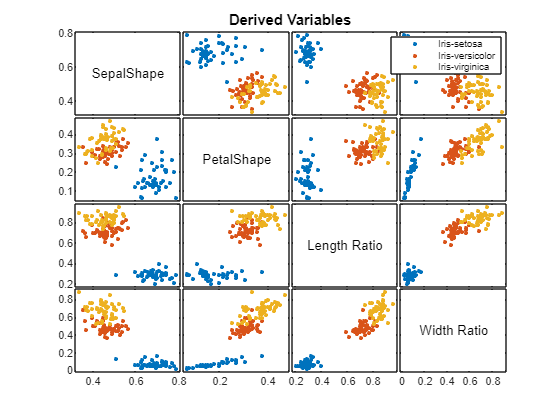

SepalShape = X.SepalWidthCm ./ X.SepalLengthCm;
PetalShape = X.PetalWidthCm ./ X.PetalLengthCm;

Length_PvsS = X.PetalLengthCm ./ X.SepalLengthCm;
Width_PvsS = X.PetalWidthCm ./ X.SepalWidthCm;

Y = [SepalShape PetalShape Length_PvsS Width_PvsS];
ynames = {'SepalShape', 'PetalShape', 'Length Ratio', 'Width Ratio'};

figure
[h, ax] = gplotmatrix(Y,[],iris.Species,color,[],[],[],'variable',ynames);
title('Derived Variables')

% saveas(gcf,'01_Iris/Derived_vars.png')

### Analyse all the variables

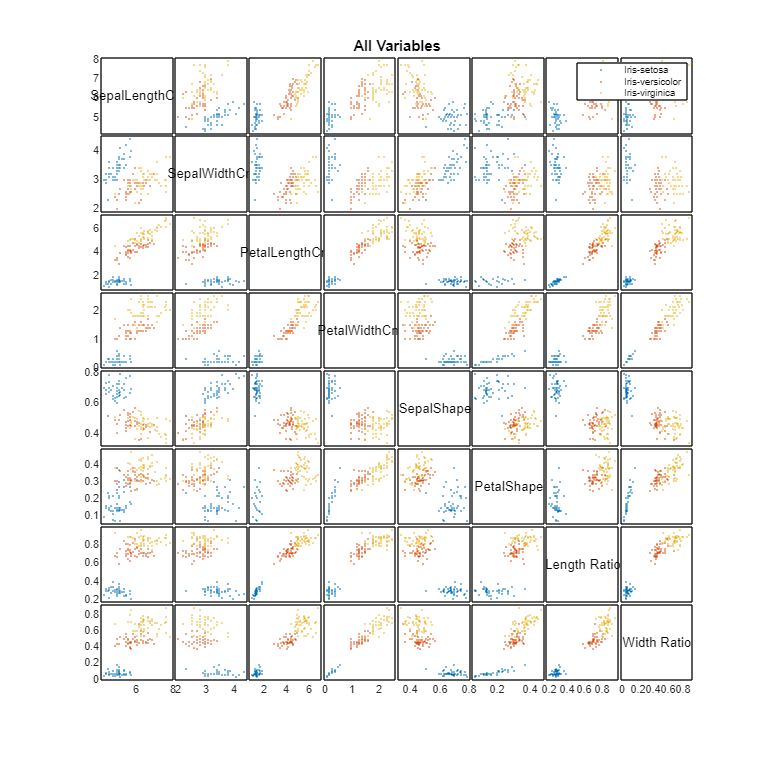

Z = [X.SepalLengthCm X.SepalWidthCm X.PetalLengthCm X.PetalWidthCm SepalShape PetalShape Length_PvsS Width_PvsS];
znames = {'SepalLengthCm', 'SepalWidthCm', 'PetalLengthCm', 'PetalWidthCm', 'SepalShape', 'PetalShape', 'Length Ratio', 'Width Ratio'};

figure
[h, ax] = gplotmatrix(Z,[],iris.Species,color,[],[],[],'variable',znames);
title('All Variables')
set(gcf, 'Position',  [100, 100, 1200, 1200])

% saveas(gcf,'01_Iris/All_vars.png')

### Select the ones which seem better suited 

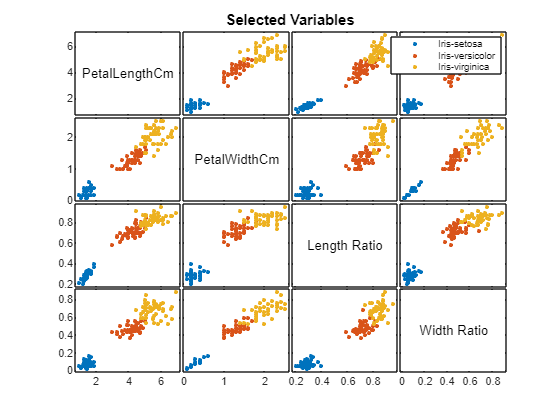

Vars = [X.PetalLengthCm X.PetalWidthCm Length_PvsS Width_PvsS];
vnames = {'PetalLengthCm', 'PetalWidthCm', 'Length Ratio', 'Width Ratio'};
figure
[h, ax] = gplotmatrix(Vars,[],iris.Species,color,[],[],[],'variable',vnames);
title('Selected Variables')

% saveas(gcf,'01_Iris/Selected_vars.png')

## Try clustering methods

### Hierarchy

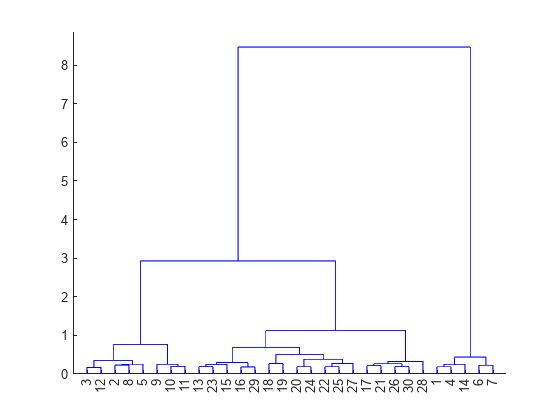

norm_factors = [1/max(X.PetalLengthCm) 1/max(X.PetalWidthCm) 1 1];

figure
hierarchy = linkage(Vars.*norm_factors, 'Ward');
dendrogram(hierarchy)

% saveas(gcf,'01_Iris/Hierarchy_tree.png')

Plot the clusters obtained with this hierarchy method when considering the 3 major branches

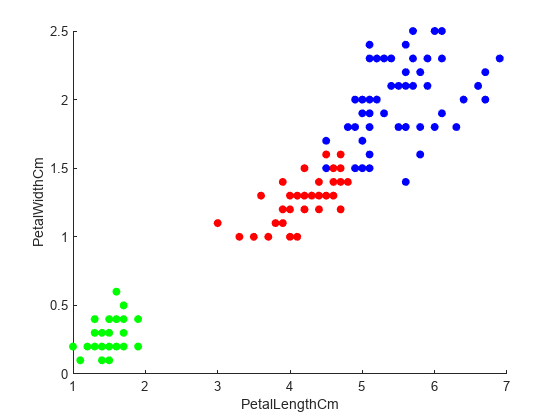

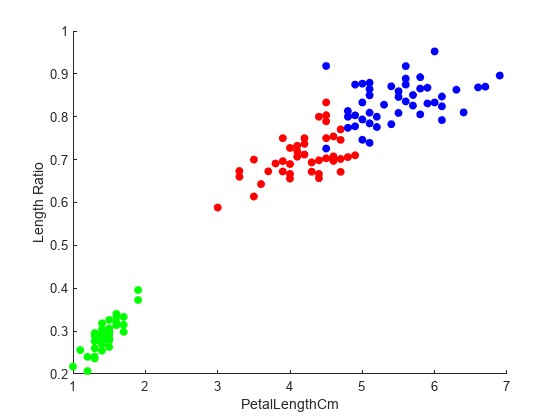

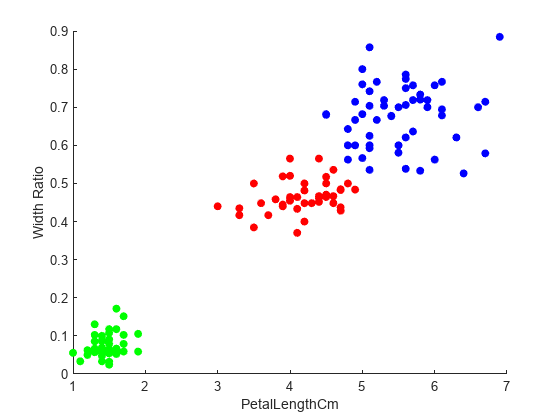

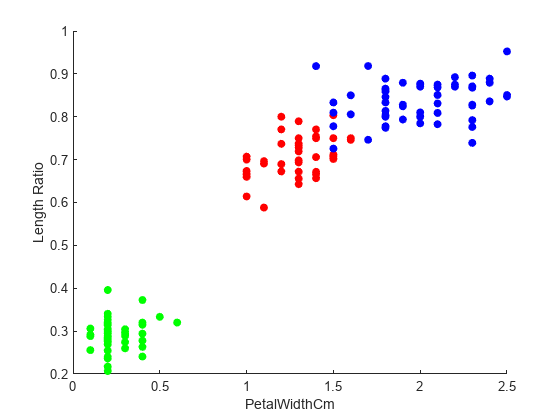

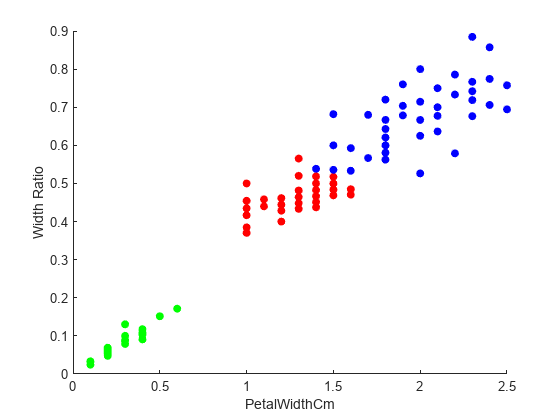

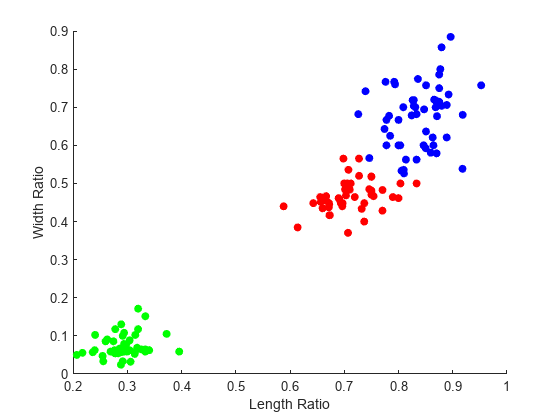

T = cluster(hierarchy,'maxclust',3);

g1 = T==1;
g2 = T==2;
g3 = T==3;

for ii=1:3
    for jj=ii+1:4
        figure
        clf
        hold on
        % Represent cluster elements
        scatter(Vars(g1,ii),Vars(g1,jj),'ro',filled='s')
        scatter(Vars(g2,ii),Vars(g2,jj),'bo',filled='s')
        scatter(Vars(g3,ii),Vars(g3,jj),'go',filled='s')
        xlabel(vnames{ii})
        ylabel(vnames{jj})
        hold off
%         saveas(gcf,strcat('01_Iris/Hierarchy_scatter_', vnames{ii}, '_', vnames{jj}, '.png') )
    end
end

How good the clustering has been?

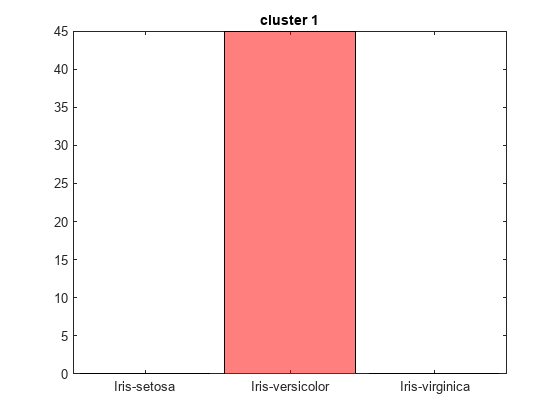

figure
histogram(iris.Species(g1), FaceColor='r', FaceAlpha=0.5)
title('cluster 1')

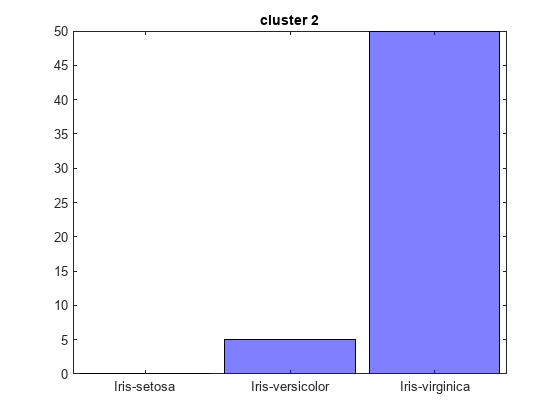

% saveas(gcf,'01_Iris/Hierarchy_cluster1.png')
figure
histogram(iris.Species(g2), FaceColor='b', FaceAlpha=0.5)
title('cluster 2')

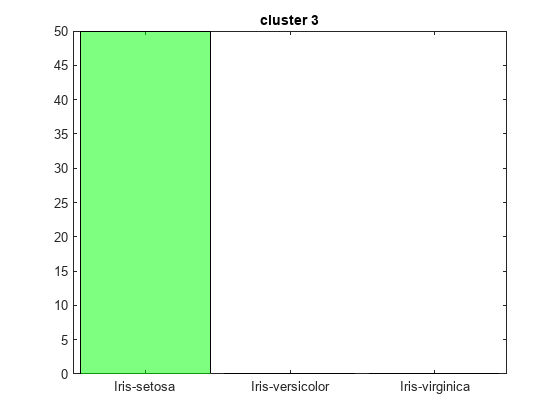

% saveas(gcf,'01_Iris/Hierarchy_cluster2.png')
figure
histogram(iris.Species(g3), FaceColor='g', FaceAlpha=0.5)
title('cluster 3')

% saveas(gcf,'01_Iris/Hierarchy_cluster3.png')

### K-means

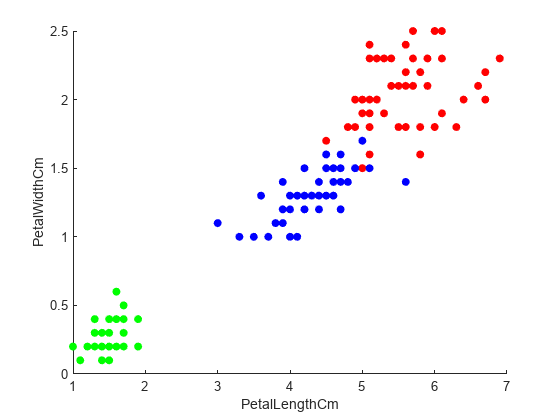

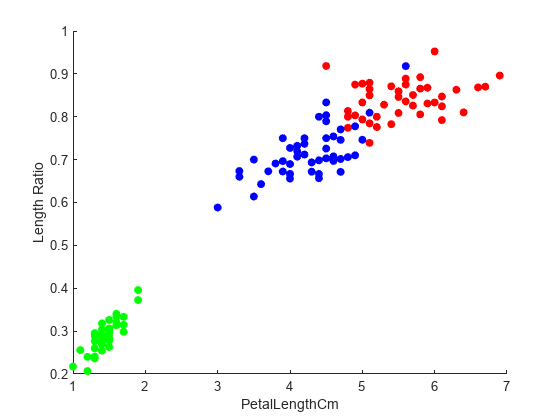

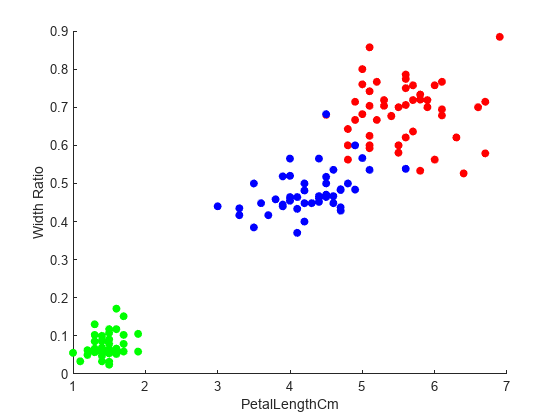

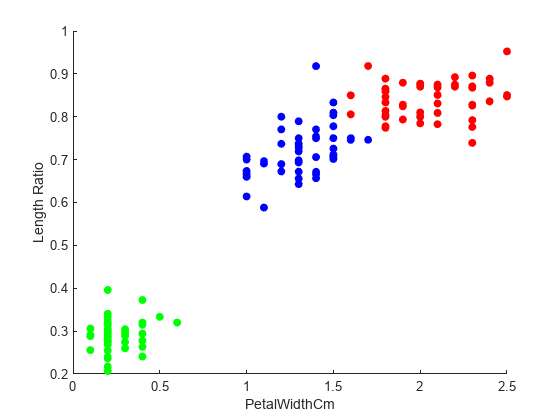

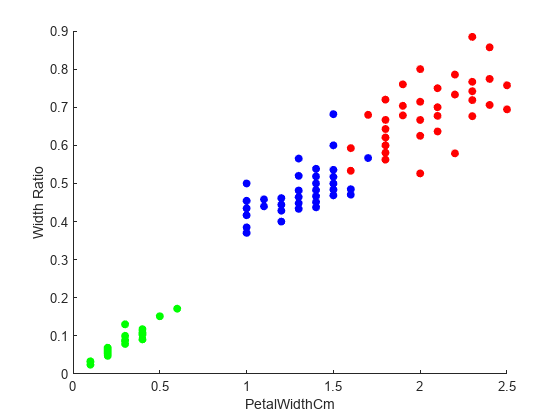

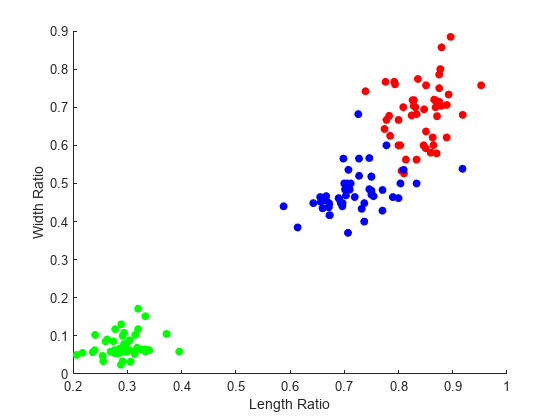

[idx,C,sumd,D] = kmeans(Vars.*norm_factors,3);

g1 = idx==1;
g2 = idx==2;
g3 = idx==3;

for ii=1:3
    for jj=ii+1:4
        figure
        clf
        hold on
        % Represent cluster elements
        scatter(Vars(g1,ii),Vars(g1,jj),'ro',filled='s')
        scatter(Vars(g2,ii),Vars(g2,jj),'bo',filled='s')
        scatter(Vars(g3,ii),Vars(g3,jj),'go',filled='s')
        xlabel(vnames{ii})
        ylabel(vnames{jj})
        hold off
%         saveas(gcf,strcat('01_Iris/Kmeans_scatter_', vnames{ii}, '_', vnames{jj}, '.png') )
    end
end

How good the clustering has been?

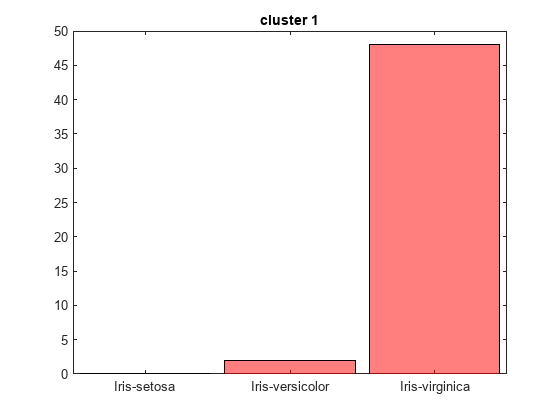

figure
histogram(iris.Species(g1), FaceColor='r', FaceAlpha=0.5)
title('cluster 1')
% saveas(gcf,'01_Iris/Kmeans_cluster1.png')

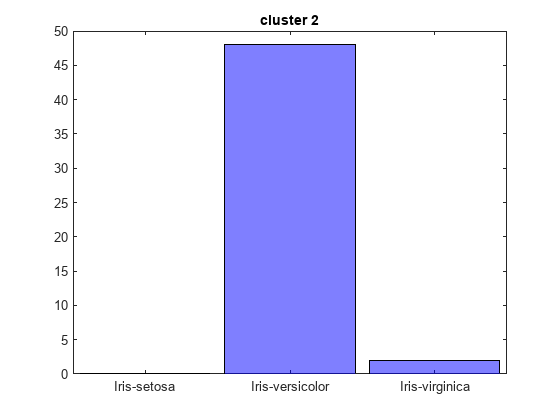

figure
histogram(iris.Species(g2), FaceColor='b', FaceAlpha=0.5)
title('cluster 2')
% saveas(gcf,'01_Iris/Kmeans_cluster2.png')

figure
histogram(iris.Species(g3), FaceColor='g', FaceAlpha=0.5)
title('cluster 3')
% saveas(gcf,'01_Iris/Kmeans_cluster3.png')